# Ejercicio 3a

### Solución sin Linealizar

% Condiciones iniciales
x0 = [0, 1, 6, 4, 2, 7];
% Intervalo de solución
tspan = [0, 10];

fg=@(t,x)[
    x(2);
    x(3);
    x(3)-18*x(5)-4*x(1)-x(4)-cosh(x(1));
    x(5);
    x(6);
    x(6)-18*x(2)-4*x(4)-x(1)-sinh(x(4))
];

[t,x]=ode45(fg,tspan,x0);

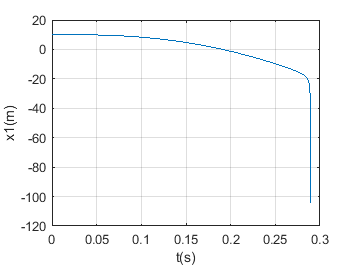


% Gráfica
plot(t,x(:,1))
grid on
xlabel('t(s)')
ylabel('x1(m)');

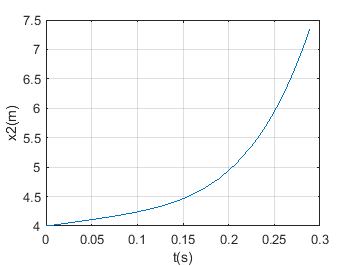


plot(t,x(:,4))
grid on
xlabel('t(s)')
ylabel('x2(m)');

### Solución linealizando

% Linealización cosh(x)


% Linealización sinh(x)